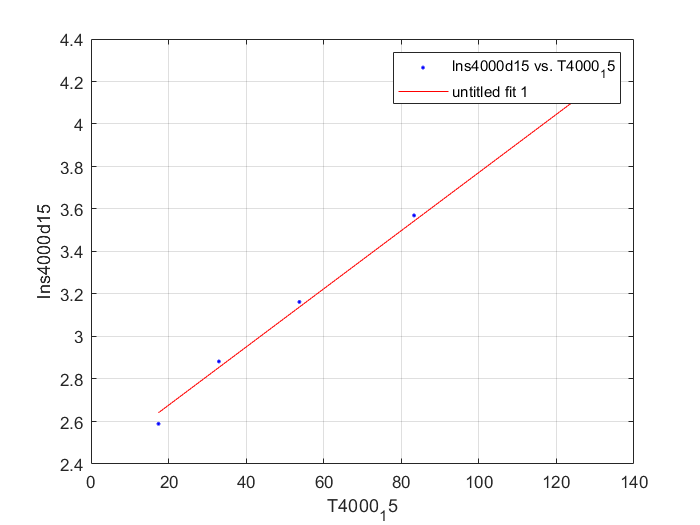

[xData, yData] = prepareCurveData( T4000_15, lns4000d15 );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'lns4000d15 vs. T4000_15', 'untitled fit 1', 'Location', 'NorthEast' );
% Label axes
xlabel T4000_15
ylabel lns4000d15
grid on


%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =     0.01369  (0.01224, 0.01514)
  %     p2 =       2.403  (2.292, 2.515)

%Goodness of fit:
 % SSE: 0.005434
  %R-square: 0.9967
 % Adjusted R-square: 0.9956
  %RMSE: 0.04256